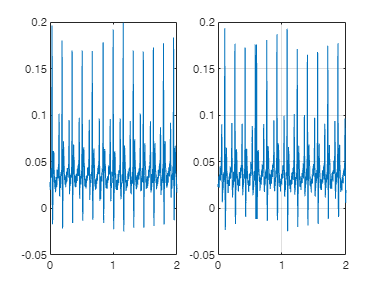

[x, fs] = audioread('D:/raterawwithduplicate/12.wav');
y1=x(100*6250:102*6250);
t1=linspace(0,length(y1)/fs,length(y1));
y2=x(105*6250:107*6250);
t2=linspace(0,length(y2)/fs,length(y2));
figure()
subplot(1,2,1)
plot(t1,y1);
subplot(1,2,2)
plot(t2,y2);
grid("on");

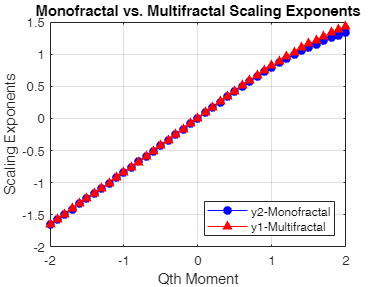

[hexp1,tauq1] = wtmm(y1);
[hexp2,tauq2] = wtmm(y2);
figure()
expplot = plot(-2:0.1:2,tauq2,'b-o',-2:0.1:2,tauq1,'r-^');
grid on;
expplot(1).MarkerFaceColor = 'b';
expplot(2).MarkerFaceColor = 'r';
legend('y2-Monofractal','y1-Multifractal','Location','SouthEast');
title('Monofractal vs. Multifractal Scaling Exponents');
xlabel('Qth Moment');
ylabel('Scaling Exponents');

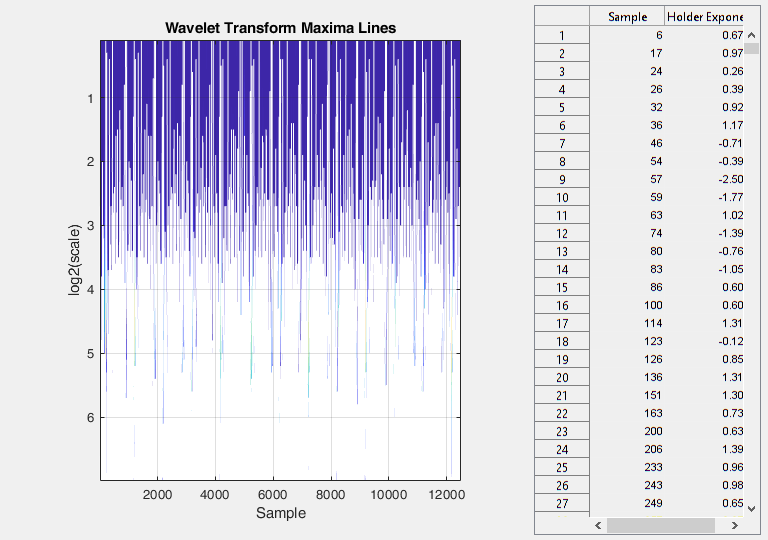

wtmm(y1,'ScalingExponent','local');

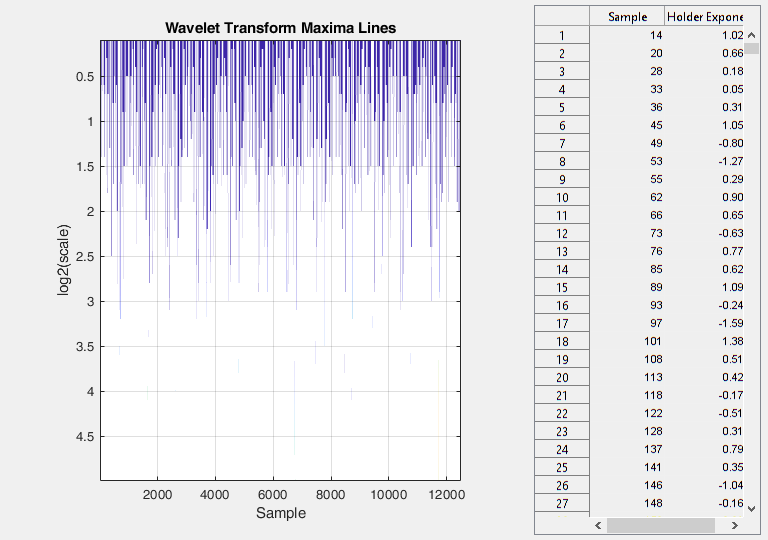

wtmm(y2,'ScalingExponent','local','NumOctaves',5);